%% Parameters
ref_location = [40.437675, -86.943750, 680]; % LLA initial position
ref_mag_field = [19.78899, -1.607, 48.9449]; % NED magnetic field

% initial state of the filter
initstate = zeros(28,1);
%orientation
initstate(1:4) = [1 0 0 0]; 
% magnetic field
initstate(23:25) = ref_mag_field;

%% Extract Raw Data
Digital_Signals = out.Digital_Signals;
Vehicle_Signals = out.Vehicle_Signals;
Orientation_all = out.Chassis_Orientation;
IMU_Signals = out.IMU_Measurements;
Reference_Signals = out.Navigation_Reference;

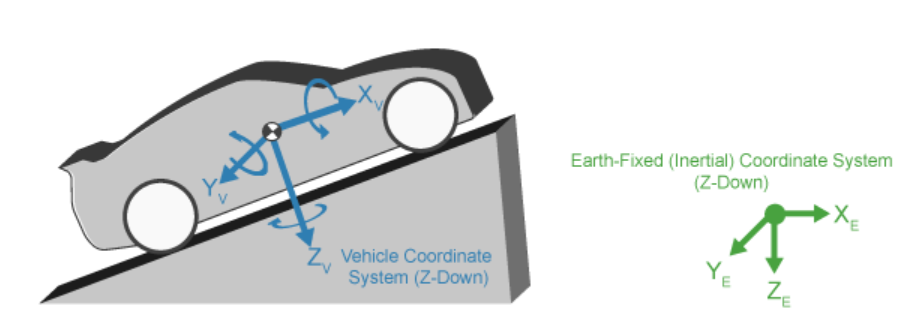

%% Before Sensor Signals
% Orientation before IMU using NED (Earth-Fixed Coordinate System)
% Phi_REF = Vehicle_Signals.veh.InertFrm.Cg.Ang.phi.Data(:);
% Theta_REF = Vehicle_Signals.veh.InertFrm.Cg.Ang.theta.Data(:);
% Psi_REF = Vehicle_Signals.veh.InertFrm.Cg.Ang.psi.Data(:);
% 
% Orientation_REF = [Phi_REF Theta_REF Psi_REF];
% Orientation = quaternion(Orientation_REF, 'euler', 'XYZ', 'frame');

Orientation = quaternion(squeeze(Orientation_all.ang_NED.data)');

% Geomagnetic Field Vector before IMU using VNED
% GeomagneticFieldVector = Orientation_all.rotm*ref_mag_field;

% Position before GPS using NED (Earth-Fixed Coordinate System)
PositionX_REF = Reference_Signals.Chassis_Position.X.data(:);
PositionY_REF = Reference_Signals.Chassis_Position.Y.data(:);
PositionZ_REF = Reference_Signals.Chassis_Position.Z.data(:);

Position = [PositionX_REF PositionY_REF PositionZ_REF];

% Angular Velocity before IMU using VNED (Vehicle-Fixed Coordinate System)
AngularVelocity_p_REF = Reference_Signals.Chassis_AngularVelocity.p.data(:);
AngularVelocity_q_REF = Reference_Signals.Chassis_AngularVelocity.q.data(:);
AngularVelocity_r_REF = Reference_Signals.Chassis_AngularVelocity.r.data(:);

AngularVelocity = [AngularVelocity_p_REF AngularVelocity_q_REF AngularVelocity_r_REF];

% Velocity before GPS using NED (Earth-Fixed Coordinate System)
VelocityX_REF = Reference_Signals.Chassis_Velocity.Xdot.Data(:);
VelocityY_REF = Reference_Signals.Chassis_Velocity.Ydot.Data(:);
VelocityZ_REF = Reference_Signals.Chassis_Velocity.Zdot.Data(:);

Velocity = [VelocityX_REF VelocityY_REF VelocityZ_REF];

% Acceleration before IMU using NED (Earth-Fixed Coordinate System)
AccelerationX_REF = Reference_Signals.Chassis_Acceleration.xddot.Data(:);
AccelerationY_REF = Reference_Signals.Chassis_Acceleration.yddot.Data(:);
AccelerationZ_REF = Reference_Signals.Chassis_Acceleration.zddot.Data(:);

Acceleration = [AccelerationX_REF AccelerationY_REF AccelerationZ_REF];

%% After Sensor Signals
% Magnetometer readings after IMU using VNED (Vehicle Coordinate System)
Magnetometer = squeeze(IMU_Signals.IMU_mag.data)';

% Position readings after IMU using NED (Earth-Fixed Coordinate System)
GPSPosition = Digital_Signals.Navigation_Sensors.pos.Data(:,:);

GPSPosition = lla2ned(GPSPosition,ref_location,'flat');

% Angular Velocity readings after IMU using VNED (Vehicle Coordinate System)
Gyroscope = squeeze(IMU_Signals.IMU_gyro.Data)';

% Velocity readings after IMU using NED (Earth-Fixed Coordinate System)
GPSVelocity = Digital_Signals.Navigation_Sensors.vel.Data(:,:);

% Acceleration readings after IMU using VNED (Vehicle Coordinate System)
Accelerometer = IMU_Signals.IMU_accel.Data(:,:)';

%% Create Datasets
groundTruth = timetable(Orientation, AngularVelocity, Position, Velocity, Acceleration, 'SampleRate', 1/t);
sensorData = timetable(Accelerometer, Gyroscope, Magnetometer, GPSPosition, GPSVelocity, 'SampleRate', 1/t);

%% Fusion Optimization
filter = insfilterAsync('State', initstate, 'StateCovariance', eye(28));
filter.ReferenceLocation = ref_location;
config = tunerconfig('insfilterAsync','MaxIterations',8);
measNoise = tunernoise('insfilterAsync');

tunedParams = tune(filter,measNoise,sensorData,groundTruth,config);

[Degree to Decimal LLA Calculator](https://www.meridianoutpost.com/resources/etools/calculators/calculator-latlong-dms-to-decimal.php/?)

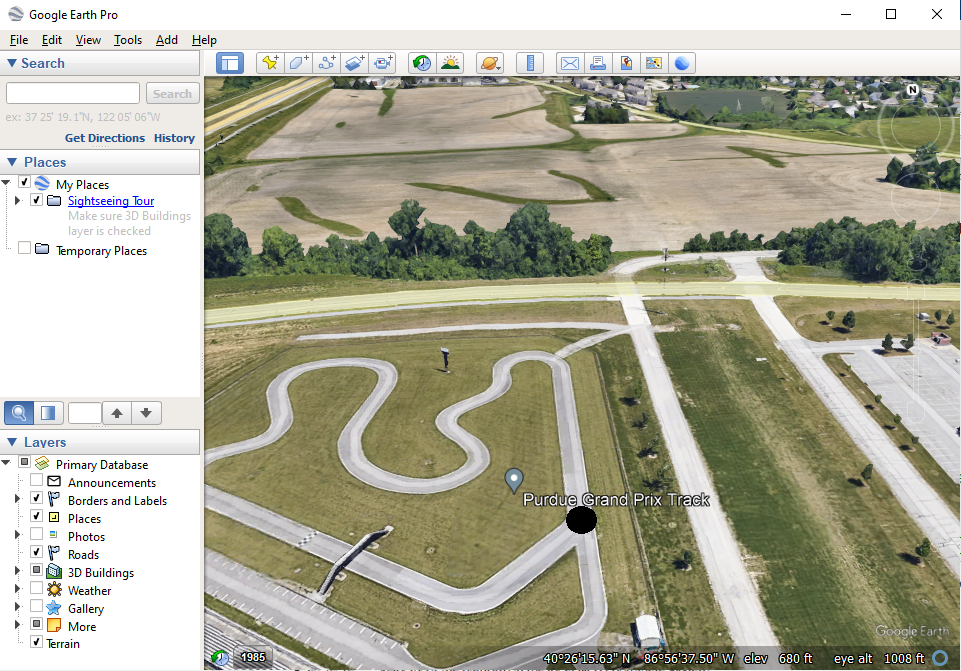

% LLA of grand prix track
PER22_Ground_Truth.refloc = [40.437675, -86.943750, 680]; % [deg deg m]

[Magnetic Field Calculator](https://www.ngdc.noaa.gov/geomag/calculators/magcalc.shtml#igrfwmm)

[More Information About Geomagnetic Fields | NCEI (noaa.gov)](https://www.ngdc.noaa.gov/geomag/geomaginfo.shtml)

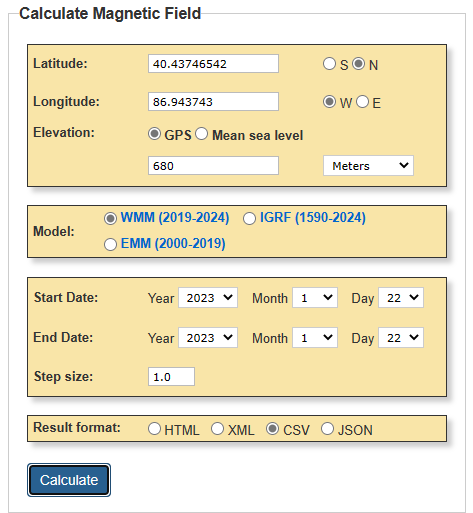

% XYZ magnetic field components at grand prix track
% note that magnetic north and true north are not equal
PER22_Ground_Truth.magField = [19.9577 -1.5449 48.4109]; % [uT uT uT]

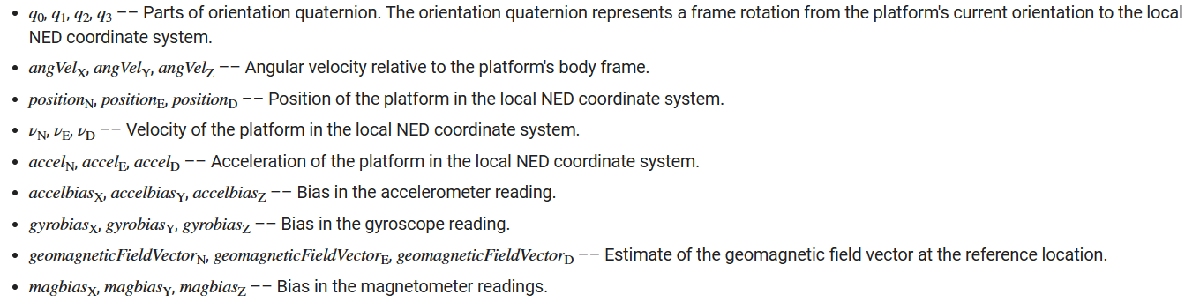

%% Process Data
num_samples = 1001;
count = 1;
orient = zeros(num_samples,1,'quaternion');
vel = zeros(num_samples,3);
acc = vel;
angVel = vel;
pos = vel;

trajectory = waypointTrajectory(Position, 'TimeOfArrival',(0:t:15), 'Orientation',Orientation, 'SampleRate', 1/t);
tInfo = waypointInfo(trajectory);

while count < num_samples+1
   [pos(count,:),orient(count),vel(count,:),acc(count,:),angVel(count,:)] = trajectory();

   count = count + 1;
end

%% Create Trajectory Struct (Sample rate of Simulation)
PER22_Ground_Truth.Fs = 1/t;
PER22_Ground_Truth.gpsFs = 1/t;

% Orientation using NED (Earth-Fixed Coordinate System)
PER22_Ground_Truth.trajData.Orientation = Orientation;

% Position using NED (Earth-Fixed Coordinate System)
PER22_Ground_Truth.trajData.Position = Position;

% Velocity using NED (Earth-Fixed Coordinate System)
PER22_Ground_Truth.trajData.Velocity = vel;

% Angular Velocity using VNED (Vehicle Coordinate System)
PER22_Ground_Truth.trajData.AngularVelocity = AngularVelocity;

% Acceleration using NED (Earth-Fixed Coordinate System)
PER22_Ground_Truth.trajData.Acceleration = acc;

% plot((0:t:15), acc(:,2))
% plot((0:t:15), angVel(:,3))
% hold on
% plot(out.yaw_error.Time, PER22_Ground_Truth.trajData.AngularVelocity(:,3))

clearvars -except PER22_Ground_Truth
save("ground_truth_data.mat");